Question 4. 

(a)(i) Plot 10 random paths up to $N=100$ time-steps $\left(i=0,1,\ldotp \ldotp \ldotp ,N\right)$using $X_0 =0$.		

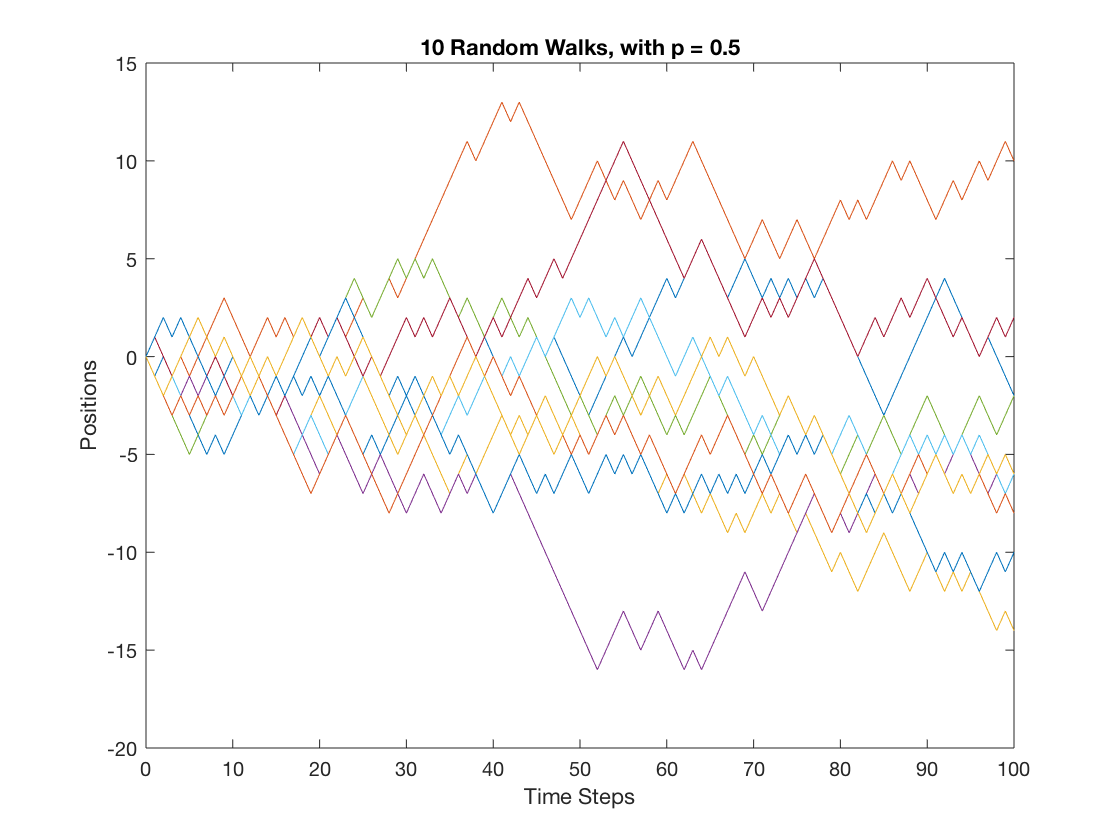

% Since we can't have indices equal to zero, we will shift our indices one
% step to the right. So X0 = x(1)

% Create an empty matrix 
rw = zeros(10,101);

% Replace rows with walks each walk
for i = 1:10
    rw(i,:) = randomwalk(0.5,101);
end

%Now plot the walks
plot(0:1:100,rw(1,:))

hold on 

for i = 2:10
    plot(0:1:100,rw(i,:))
end

title('10 Random Walks, with p = 0.5')
xlabel('Time Steps')
ylabel('Positions')
% No point in putting legend 

hold off

(ii) Construct a histogram of the position reached at time $i=5$ of 100 sample paths. The probability distribution function is given by 


$$P\left(X=x\right)=\left\lbrack \begin{array}{c}
N-1\\
\frac{x+N-1}{2}
\end{array}\right\rbrack p^{\frac{x+N-1}{2}} {\left(1-p\right)}^{\frac{N-1-x}{2}}$$


Here, $x\;$is position, N is the time step (hence, N-1 steps have been made), and$\;p$ is the probability of going up along y axis. 

Let $u\;$be the number of steps of taken in the positive direction of y-axis, and let $d$ be the number of steps taken in negative direction. Consider the following:


$$x=u-d\;,N-1=u+d$$



$$\Rightarrow 2u\;-\;N+1=x$$


$u\;$can take values $0\;\mathrm{to}\;N-1$. Every position is uniquely determined by the number steps taken in the positive direction (and also in the negative direction, since one determines the other). Therefore, for a given $N$, $x$ can take values $-N+1\;\mathrm{to}\;N-1\;\;\left(=\;2\left(N-1\right)-N+1\;\right)$. 

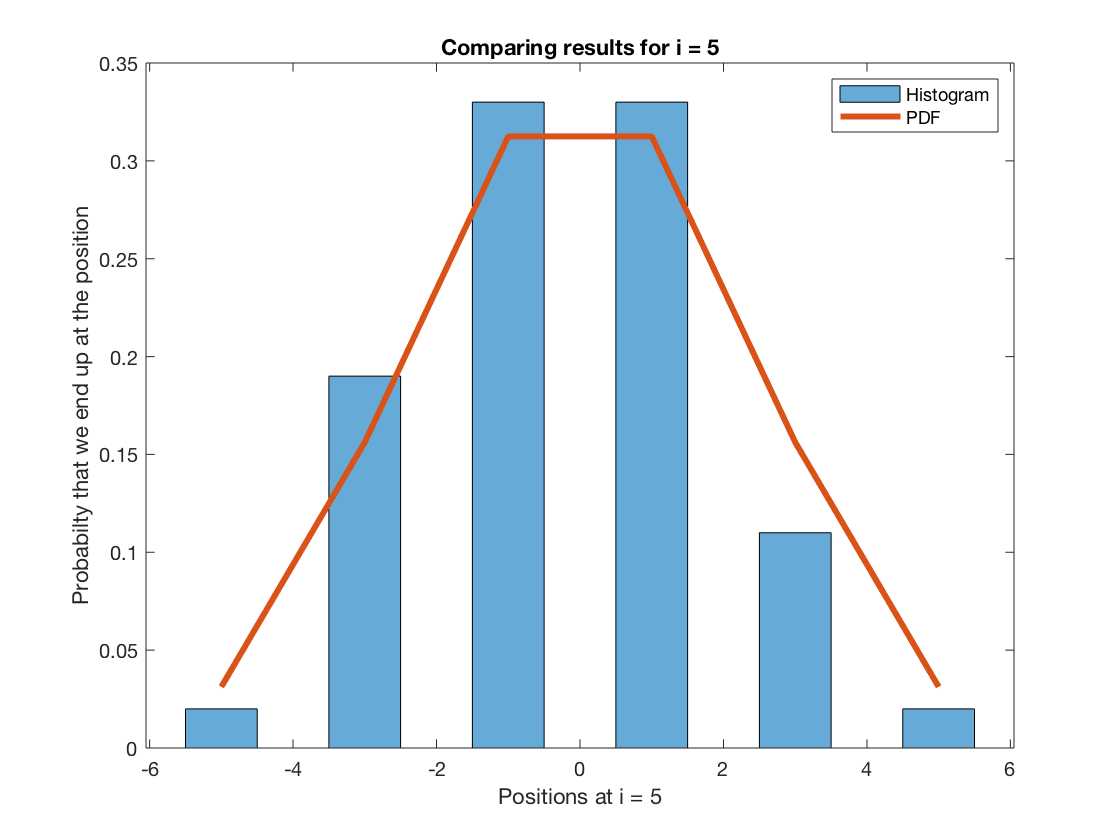

%Record the walks 
for i = 1:100
    rw(i,:) = randomwalk(0.5,101);
end

% X5 = x(6)
positionsat5 = rw(:,6);
%Plot histogram and normalize values
histogram(positionsat5,'Normalization',"pdf")

hold on 

%Plot the pdf
bin5 = @(x) nchoosek(5,(x+5)/2)*power(1/2,5);
for i = 1:6
    bernoulli5(i) = bin5(2*(i-1) - 5 );
end
plot(-5:2:5,bernoulli5,'linewidth',3)

title('Comparing results for i = 5')
xlabel('Positions at i = 5')
ylabel('Probabilty that we end up at the position')
legend('Histogram','PDF')

hold off

(iii) Repeat for $i=20$

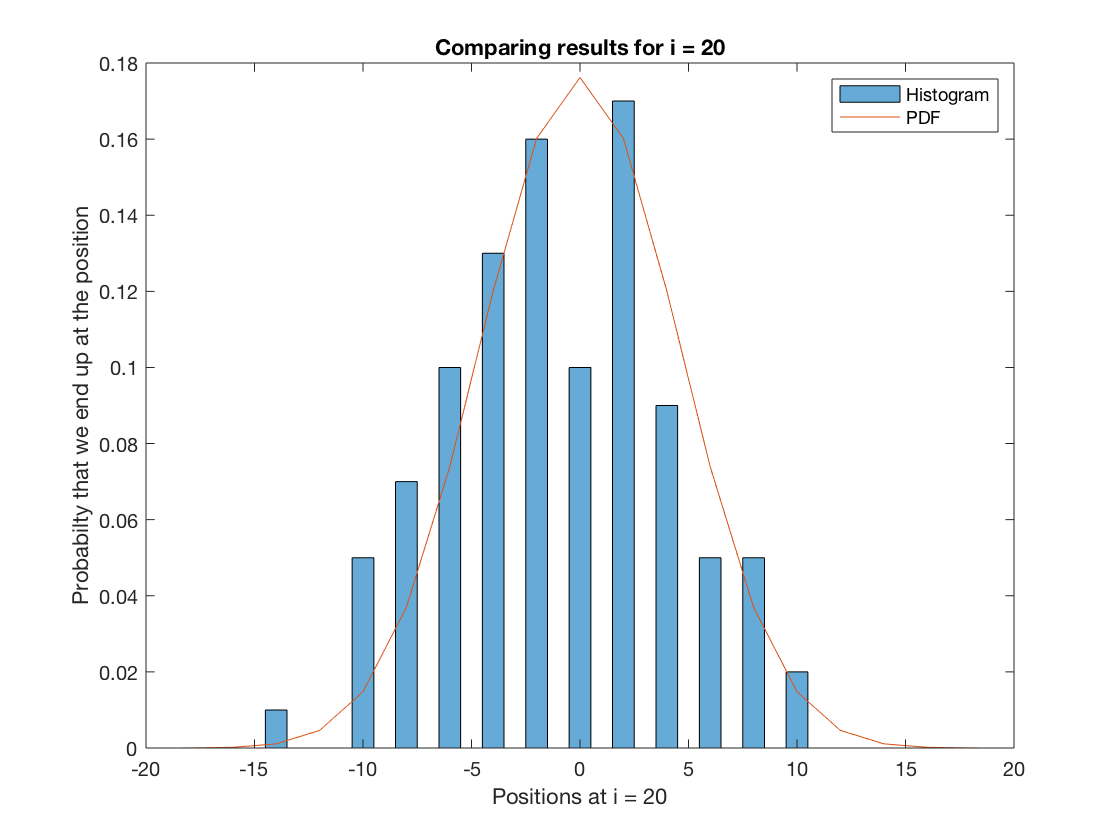

% X20 = x(21)
positionsat20 = rw(:,21);
%Plot histogram and normalize values
histogram(positionsat20,'Normalization','pdf')

hold on 

%Plot the pdf
bin20 =@(x) nchoosek(20,(x+20)/2)*power(1/2,20);

for i = 1:21
    bernoulli20(i) = bin20(2*(i-1) - 20);
end

plot(-20:2:20,bernoulli20)

title('Comparing results for i = 20')
xlabel('Positions at i = 20')
ylabel('Probabilty that we end up at the position')
legend('Histogram','PDF')

hold off

(iv) Record 1000 random walks. Choose random time step, let's say $i=50$, plot the histogram and compare results to the pdf. 

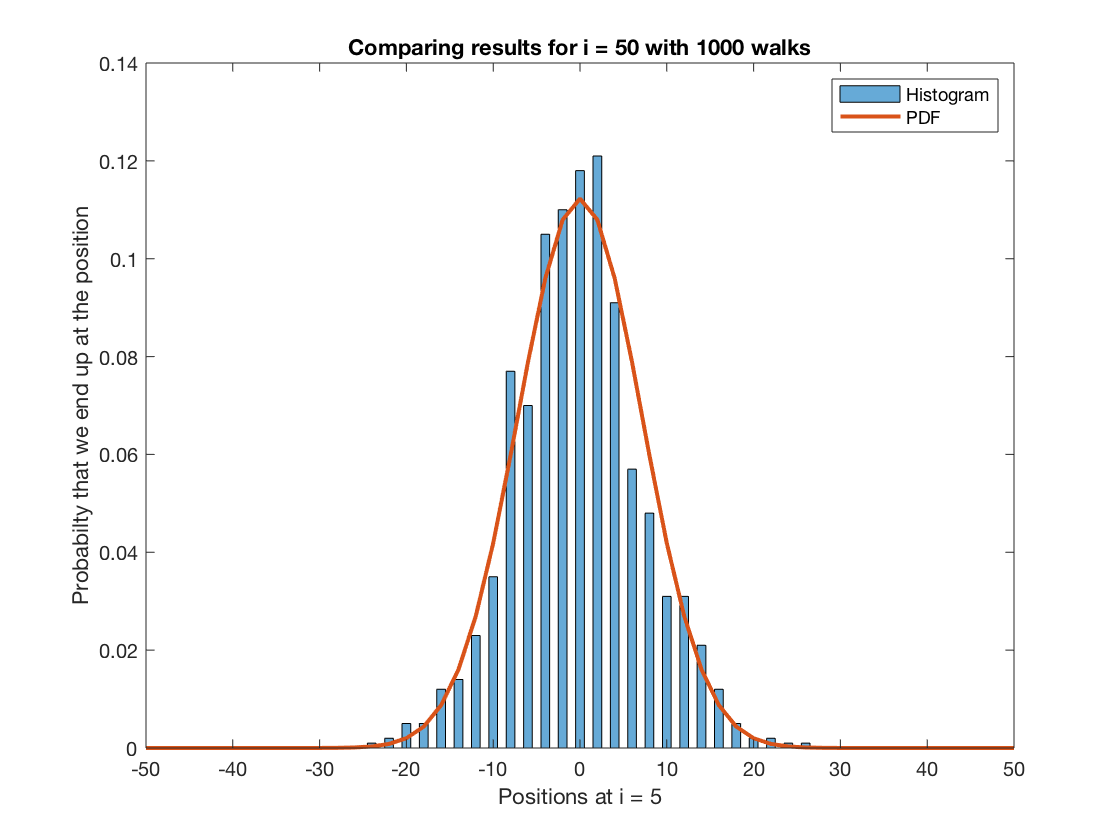

for i = 1:1000
    rw(i,:) = randomwalk(0.5,101);
end

finalpositions = rw(:,51);
%Plot histogram and normalize values
histogram(finalpositions,'Normalization','pdf')

hold on 

bin100 = @(x) nchoosek(50,(x+50)/2)*power(0.5,50);

for i = 1:51;
    bernoulli100(i) = bin100(2*(i-1) - 50);
end

plot(-50:2:50,bernoulli100,"linewidth",2)

title('Comparing results for i = 50 with 1000 walks')
xlabel('Positions at i = 5')
ylabel('Probabilty that we end up at the position')
legend('Histogram','PDF')

hold off

It is easy to see that when we increase $N$, our recordings are more compatible with the probability density function. 

(b) (i) Plot 100 random paths up to N = 100 time-steps $\left(i=0,1,\ldotp \ldotp \ldotp ,N\right)$ using $X_0 =0$ and $p=0\ldotp 2$ 		

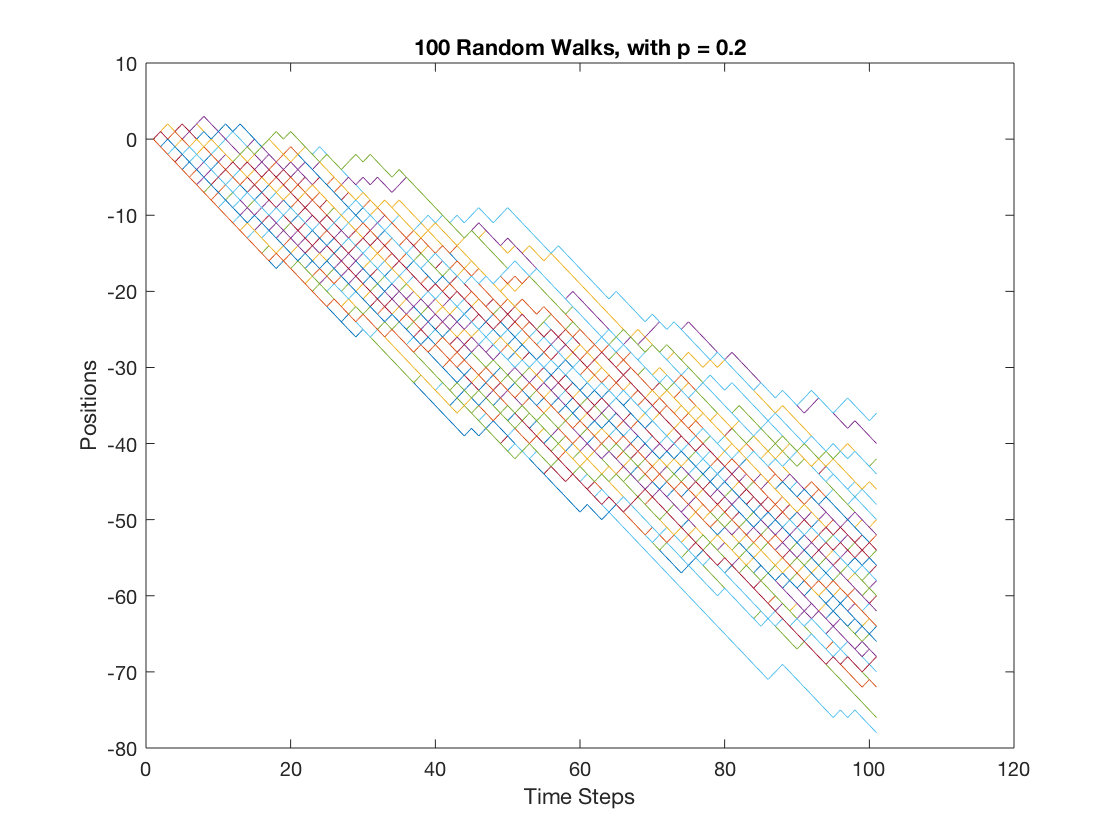

clear 
clc

rw = zeros(100,101);

%Record the random walks 
for i = 1:100
    rw(i,:) = randomwalk(0.2,101);
end

% Plot the random walkswalks

plot(rw(1,:))

hold on 

for i = 2:100
    plot(rw(i,:))
end

title('100 Random Walks, with p = 0.2')
xlabel('Time Steps')
ylabel('Positions')
% No point in putting legend 

hold off

(ii) Construct a histogram of the position reached at time $i=5$ of 100 sample paths.

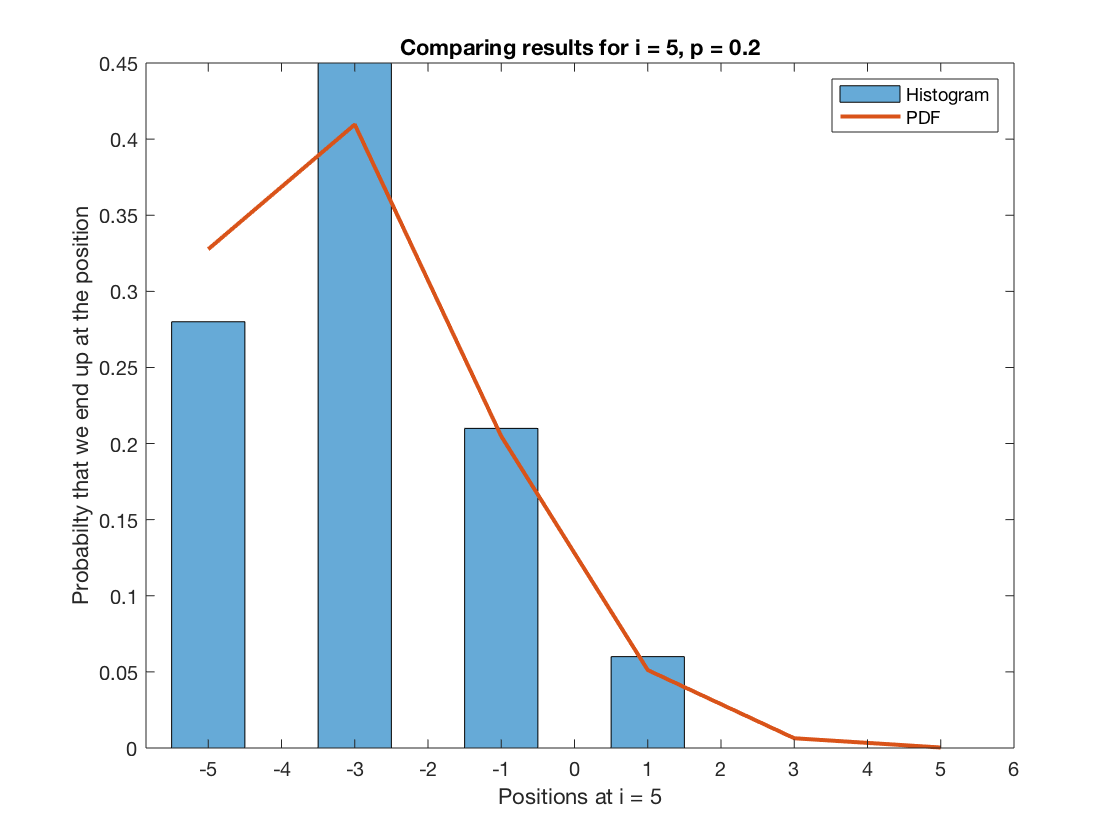

% X5 = x(6)
newpositionat5 = rw(:,6);

%Plot histogram and normalize values
histogram(newpositionat5,'Normalization','pdf')

hold on


% Plot pdf to compare
newbin5 = @(x) nchoosek(5,(x+5)/2)*power(0.2,(x+5)/2)*power(0.8,(5-x)/2);

for i = 1:6;
    newbernoulli5(i) = newbin5(2*(i-1) - 5);
end

plot(-5:2:5,newbernoulli5,'linewidth',2)

title('Comparing results for i = 5, p = 0.2')
xlabel('Positions at i = 5')
ylabel('Probabilty that we end up at the position')
legend('Histogram','PDF')
hold off 

FUNCTION FOR RANDOM WALK

function x = randomwalk(p, N)
    x(1) = 0;
    for i = 2:N
        u = rand;
        if u < p
            x(i) = x(i-1) + 1;
        else
            x(i) = x(i-1) - 1;
        end
    end 
end